clear all
close all
clc

## 12.2.6

% c)
c = 20*log10(sqrt(30)) % db

c = 14.7712

% d)
d = 20*log10(6/(50000)) % db

d = -78.4164

## 12.2.7

% c)
c = 10^(-12/20)

c = 0.2512

% d)
d = 10^(-66/20)

d = 5.0119e-04

## 12.2.8

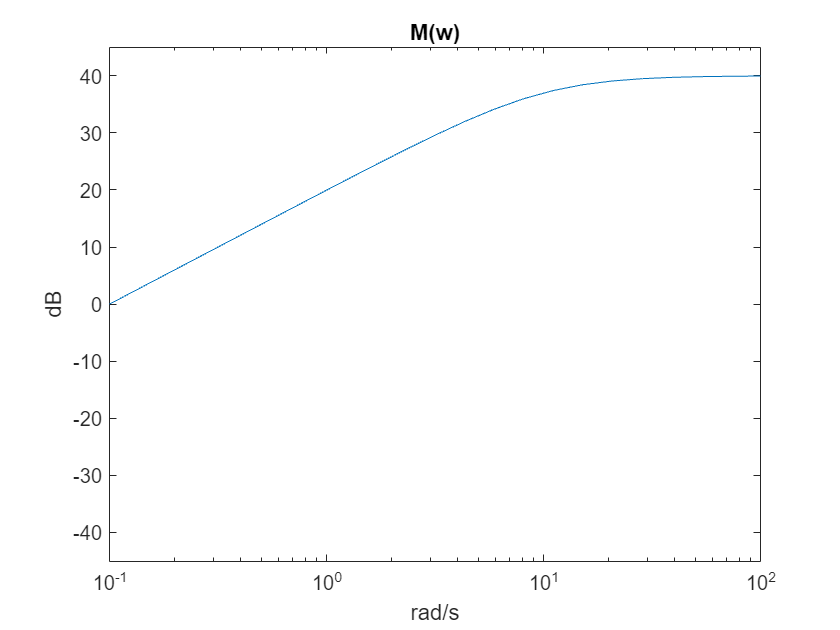

syms w

% a)
const = 10;
myzeros = w;
Hw = (100j*w)/(10+1j*w);
mypoles = 1+1j*w/10;
plotmag(mypoles,myzeros,const,100,45);

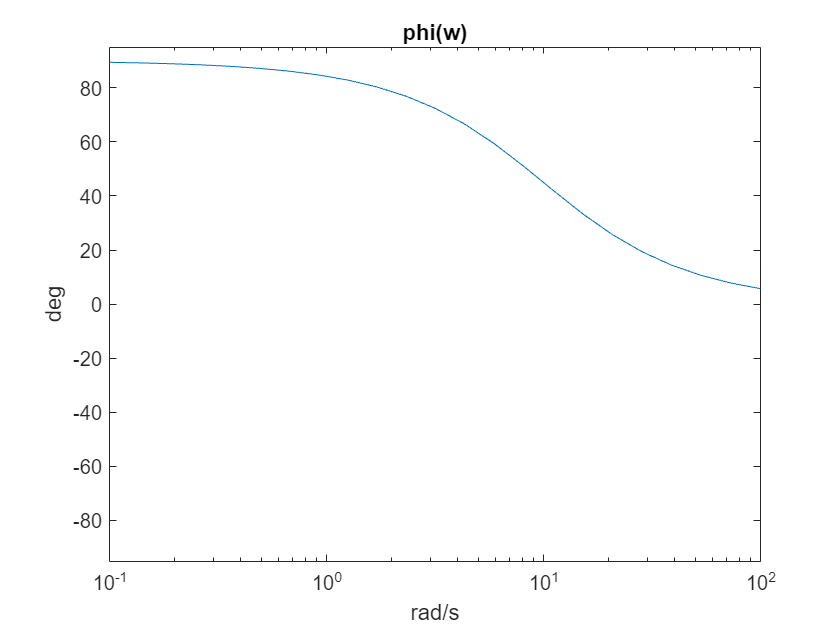

plotang(Hw,100,95);

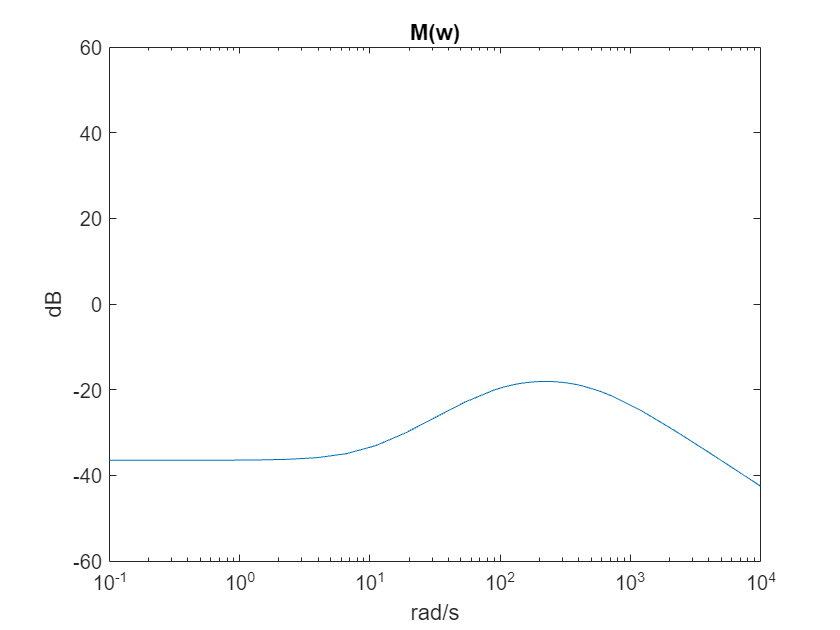


% e)
const = 3/200;
Hw = 30*(10+1j*w)/((200+2*1j*w)*(1000+2*1j*w));
zero1 = 1+1j*w/10;
pole1 = 1+1j*w/100;
pole2 = 1+1j*w/500;
poles= [pole1,pole2];
myzeros = zero1;
plotmag(poles,myzeros,const,10000,0);

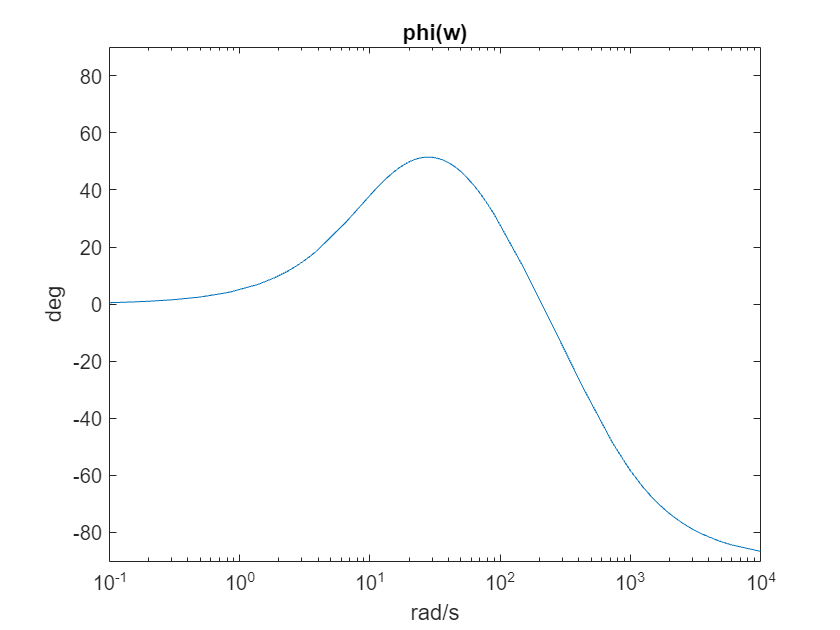

plotang(Hw,10000,90);

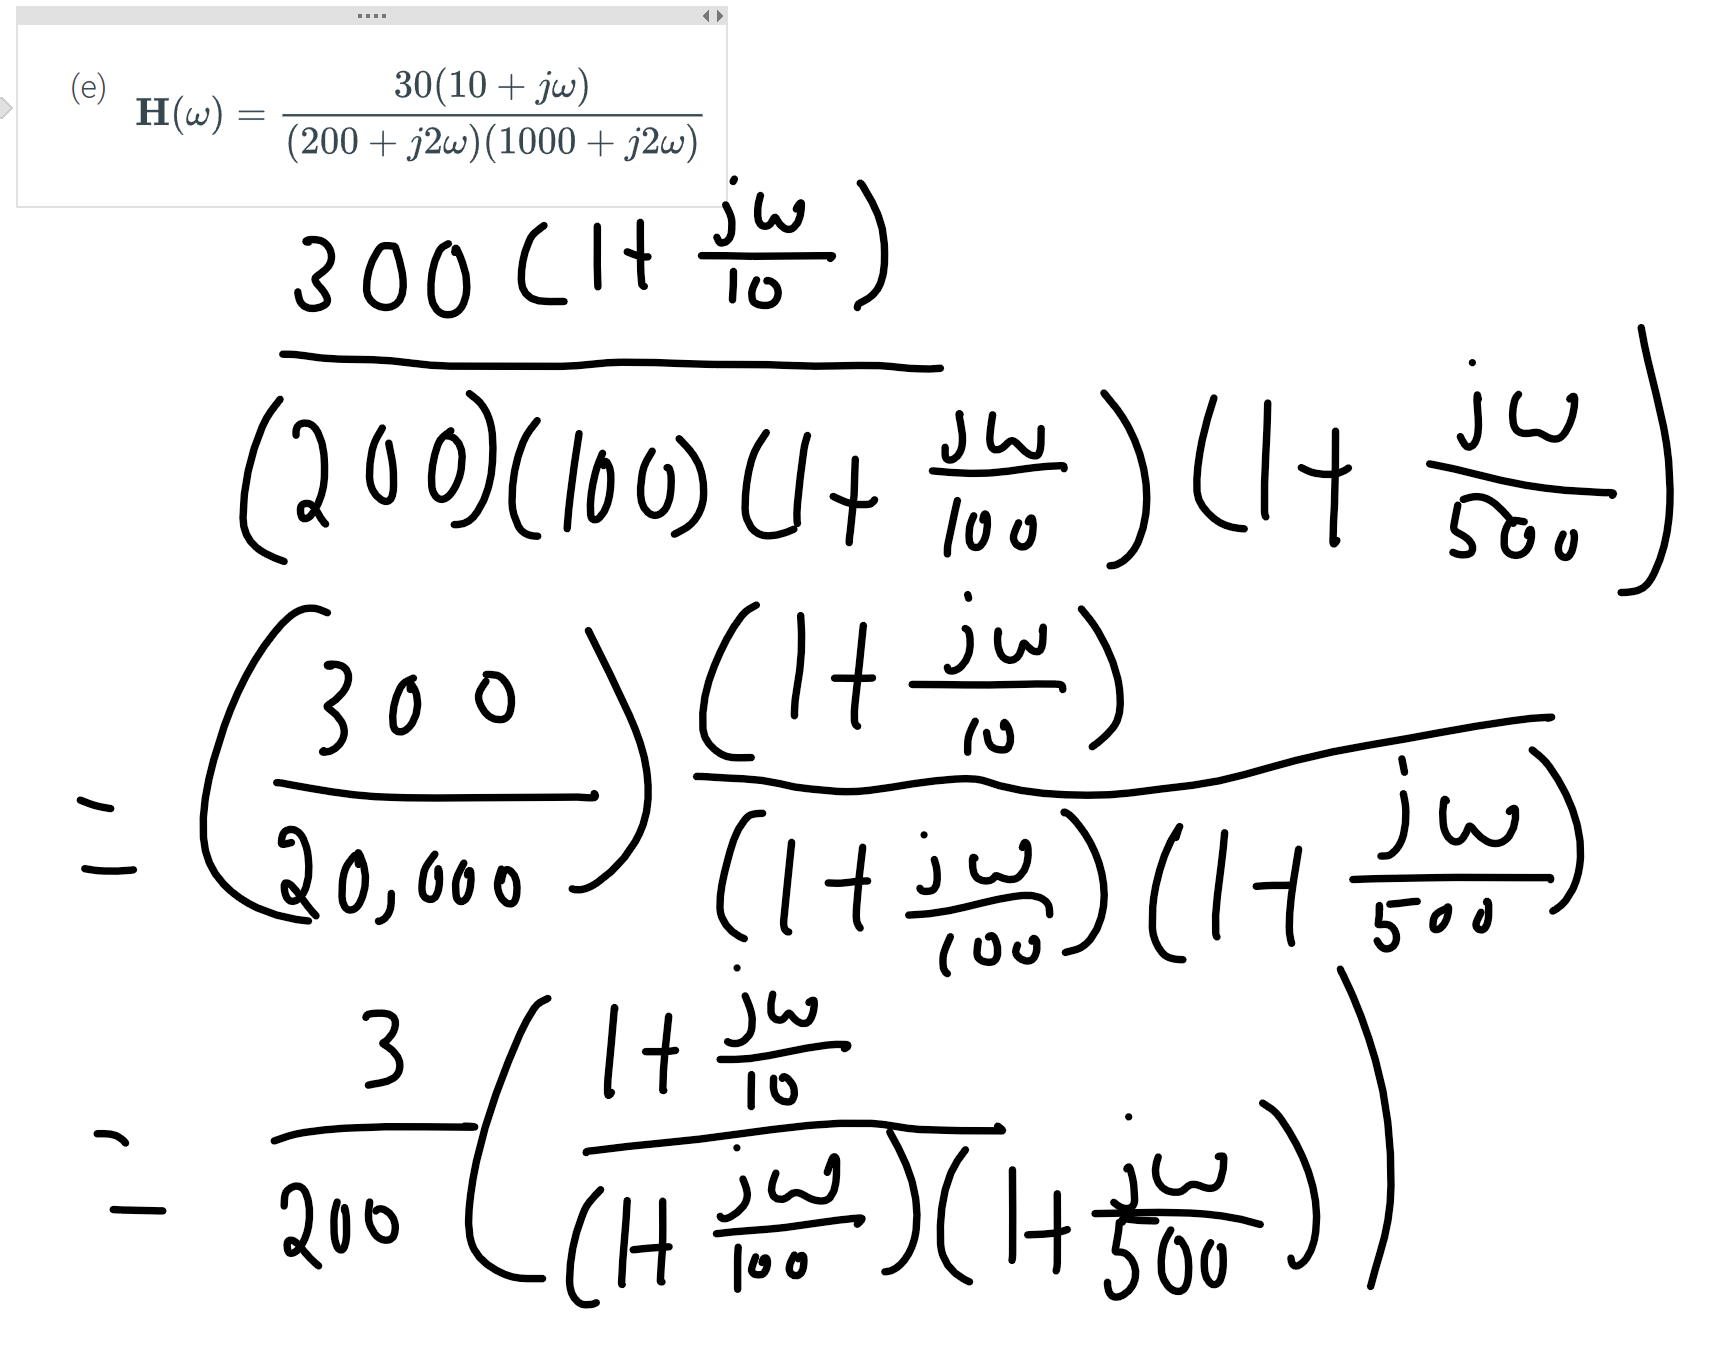

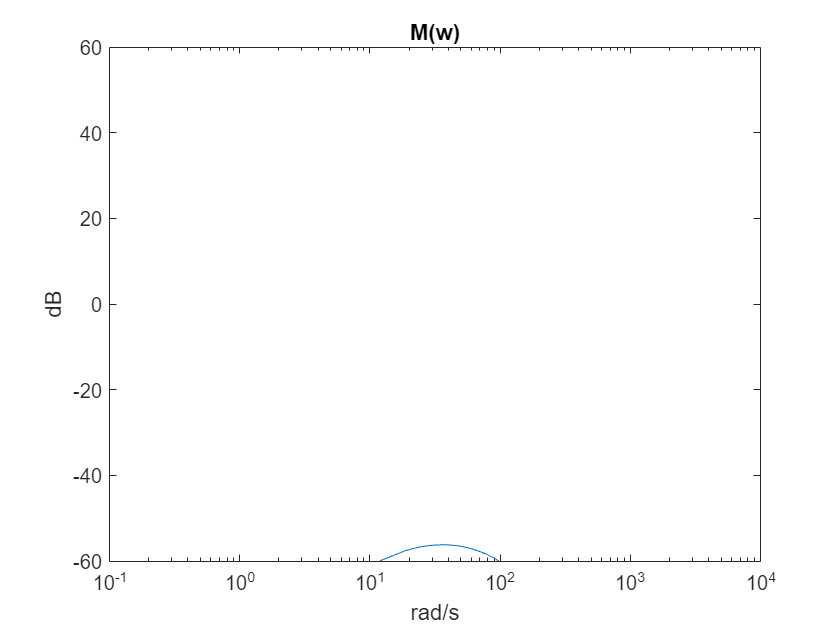

% f)
const = 1/(100^2);
Hw = 100*1j*w/((100+1j*w*5)*(100+1j*w)^2);
zero1 = w;
pole1 = 1+1j*w/20;
pole2 = 1+1j*w/100;
pole3 = pole2;
poles= [pole1,pole2,pole3];
myzeros = zero1;
plotmag(poles,myzeros,const,10000,0);

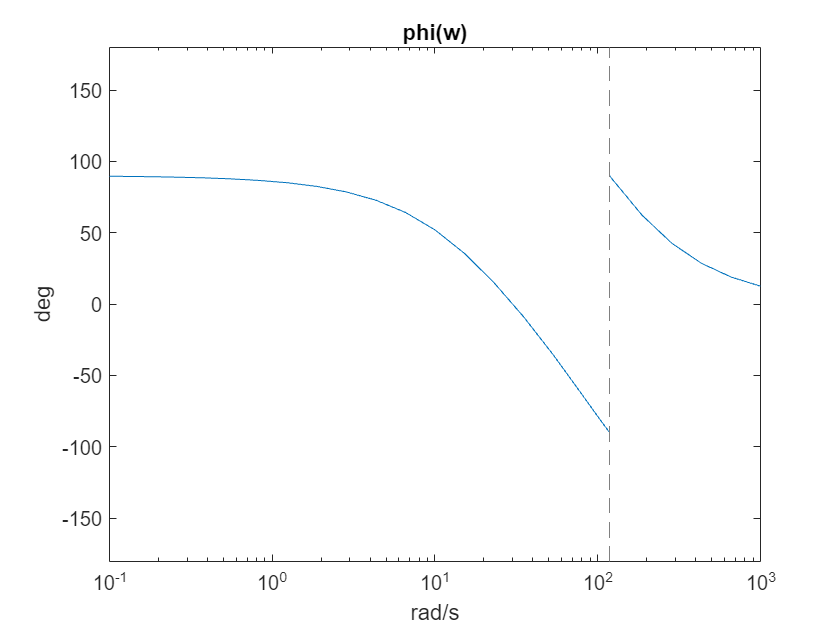

plotang(Hw,0,0);

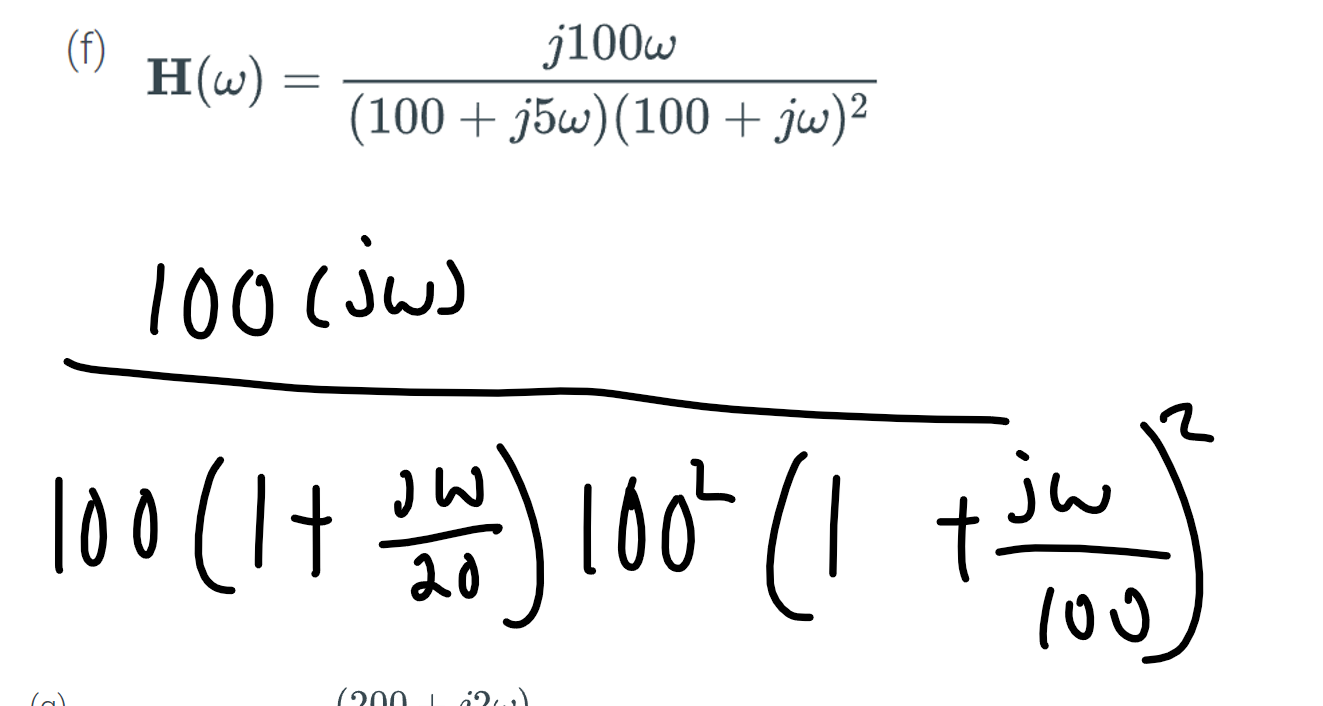

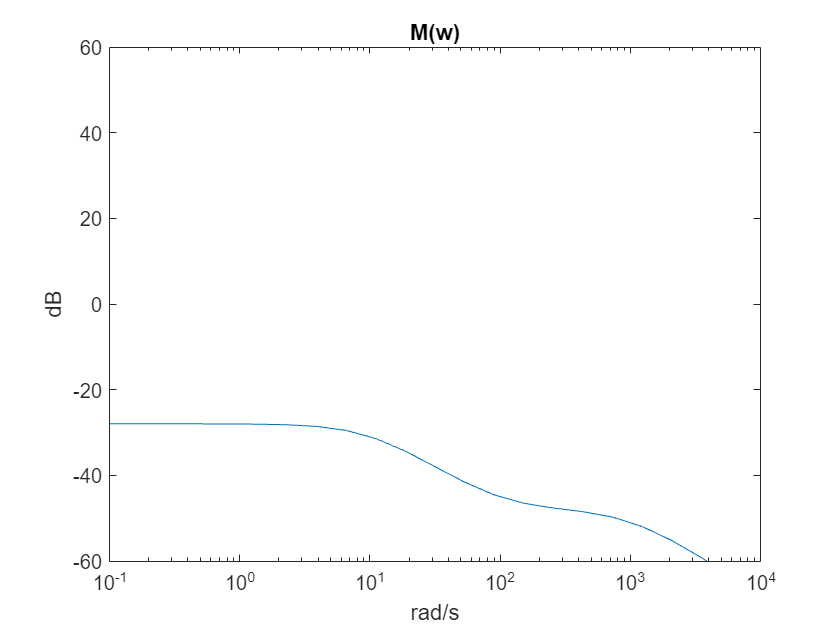

   
% g)
const = 200/(50*100);
Hw = (200+1j*2*w)/((50+1j*w*5)*(1000+1j*w));
zero1 = 1+(1j*w/100);
pole1 = 1+1j*w/10;
pole2 = 1+1j*w/1000;
poles= [pole1,pole2];
myzeros = zero1;
plotmag(poles,myzeros,const,10000,0);

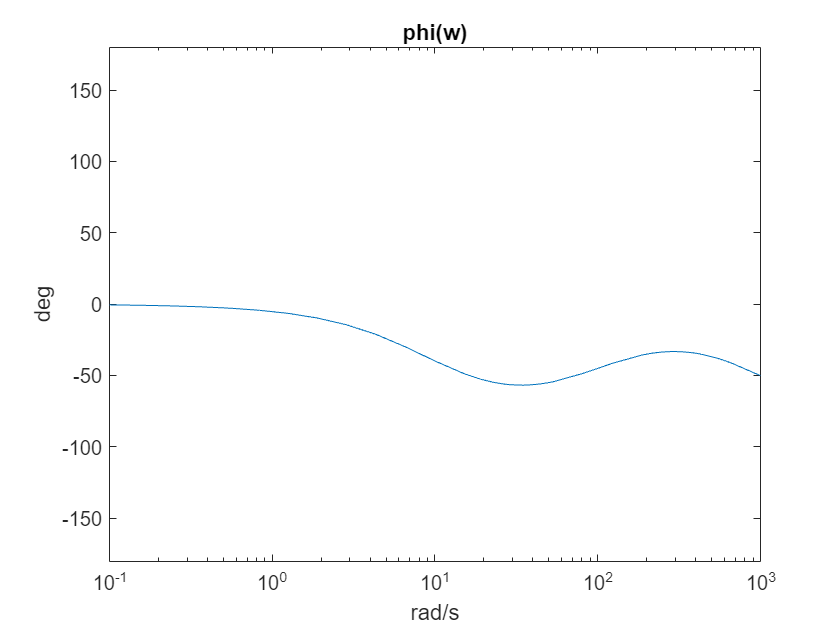

plotang(Hw,0,0);

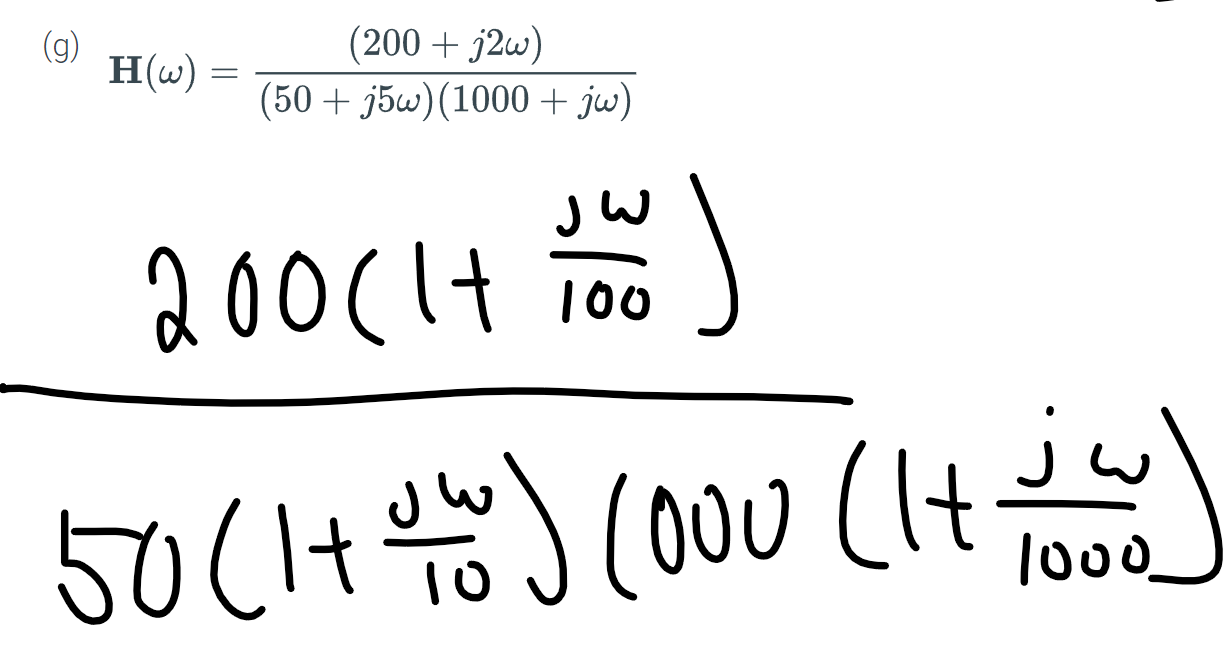

## 12.3.4

R = 100;
L = .01;
C = .0004

C = 4.0000e-04

Wzero = 1/sqrt(L*C)

Wzero = 500

B = 1/(R*C)

B = 25

Q = Wzero/B

Q = 20

Wone = Wzero*(-1/(2*Q)+sqrt(1+1/(4*Q^2)))

Wone = 487.6562

Wtwo = Wzero*(1/(2*Q)+sqrt(1+1/(4*Q^2)))

Wtwo = 512.6562

## Function For Plotting Magnitude and Angle Of Transfer Function

function [] = plotmag(poles,zeros,const,myxlim,myylim)
    if(myxlim == 0)
        myxlim = 1000;
    end
    if(myylim == 0)
        myylim = 60;
    end
    Mdbw = 20*log10(const);
    for i=1:1:length(zeros)
        Mdbw = Mdbw + 20*log10(abs(zeros(i)));
    end
    for i=1:1:length(poles)
        Mdbw = Mdbw - 20*log10(abs(poles(i)));
    end
    fplot(Mdbw);
    hold off
    set(gca,'XScale','log');
    xlim([0 myxlim])
    ylim([-myylim myylim])
    xlabel('rad/s')
    ylabel('dB')
    title('M(w)')
    hold off
end
function [] = plotang(Hw,myxlim,myylim)
    if(myxlim == 0)
        myxlim = 1000;
    end
    if(myylim == 0)
        myylim = 180;
    end
    phasew = atan(imag(Hw)/real(Hw));
    fplot(rad2deg(phasew));
    set(gca,'XScale','log');
    xlim([0 myxlim])
    ylim([-myylim myylim])
    xlabel('rad/s')
    ylabel('deg')
    title('phi(w)')
    hold off
end
